# Confime_measure.mlx

% ============================================================

%  Copyright © 2023-2025 Xiaofeng Dai (xiaofend@umich.edu)

%  SPDX-License-Identifier: GPL-3.0-or-later

%

%  This program is free software: you can redistribute it and/or modify

%  it under the terms of the GNU General Public License as published by

%  the Free Software Foundation, either version 3 of the License, or

%  (at your option) any later version.

%

%  This program is distributed in the hope that it will be useful,

%  but WITHOUT ANY WARRANTY; without even the implied warranty of

%  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the

%  GNU General Public License for more details.

%

%  You should have received a copy of the GNU General Public License

%  along with this program (LICENSE file in the repository root).

%  If not, see <https://www.gnu.org/licenses/>.

%

%  Tested with: MATLAB R2024a and R2022a

% ============================================================

### SINGLE-TRAJECTORY CONFINEMENT ANALYSIS

% ----------------------------------------------------

% * Input:  `Traj_bytrack.mat` containing cell-array of individual single-

%   molecule tracks (each a table with columns [frame, x, y, ...]).

% * Output: Distributions and per-track metrics: Radius of gyration (Rg),

%   convex-hull confinement area, confinement index (CI) for a window of

%   `num_step`, and first‑passage time (FPT) to exit a circle of radius

%   `radius` from any of the `num_center` closest points to the track’s

%   centre of mass.

% * Helper functions appear at the bottom: `Cal_Rg`, `Cal_confArea`,

%   `Cal_CI`, `Cal_FPT`, and `StepSizeDis`.

% ----------------------------------------------------

### Load data (Trajectory from dataset organized by tracks)

Folder=uigetdir('Example_Folder/subfolder');
load([Folder,filesep,'Results_Filter',filesep,'Traj_bytrack.mat'])
Num_traj = length(Traj_bytrack);

### Plot step size distribution & # of steps distribution

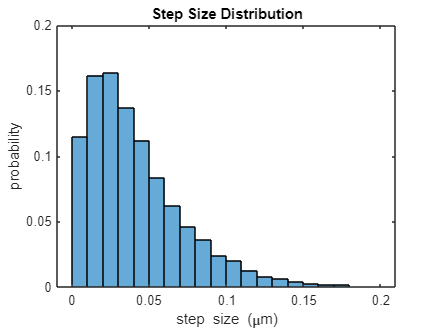

Dis_stepsize = StepSizeDis(Traj_bytrack);

median(Dis_stepsize)

ans = 0.0341

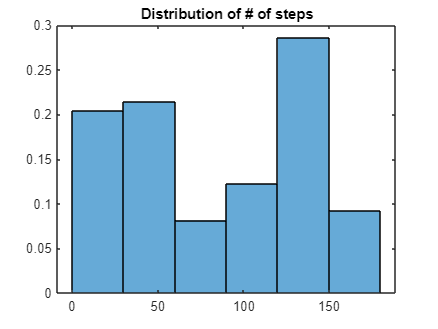


buff = zeros(Num_traj,1);
for i = 1:Num_traj
    buff(i) = height(Traj_bytrack{i});
end
figure
histogram(buff,'Normalization','probability')
title('Distribution of # of steps')

clear i buff

Set radius and number of centers used for 'First Passage Time' (FPT)  analysis

Set num_step used for 'Confinement Index' analysis

Calcualte 'Radius of Gyration', 'Confined Area', 'Confine Index', and 'FPT'

radius = 0.03;      % μm for first‑passage circle
num_center = 5;     % # candidate circle centres
num_step = 80;      % window for confinement index

Store_Rg = zeros(Num_traj,1);
Store_confArea = zeros(Num_traj,1);
Store_CI = zeros(Num_traj,1);
Store_FPT = zeros(Num_traj,1);

parfor i = 1:Num_traj
    traj = Traj_bytrack{i};
    Store_Rg(i) = Cal_Rg(traj);
    Store_confArea(i) = Cal_confArea(traj);
    Store_CI(i) = Cal_CI(traj,num_step);
    buff = Cal_FPT(traj,radius,num_center);
    if isempty(buff)
        Store_FPT(i) = NaN;
    else
        Store_FPT(i) = buff;
    end
end
clear i traj buff
Store_CI(Store_CI==0)=[];

### plot results

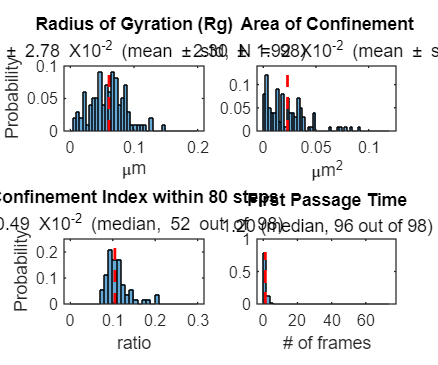

figure('Position', [10 10 1200 1000])
subplot(2,2,1)
histogram(Store_Rg,'Normalization','probability','BinEdges',(0:0.005:0.2))
hold on
plot(repmat(mean(Store_Rg),20,1),linspace(0,max(ylim(gca)),20),'LineWidth',2,'Color','red','LineStyle','--')
title('Radius of Gyration (Rg)','FontSize',16)
% Prepare string
str = { [ sprintf('%.2f ± %.2f X10^{-2} (mean ± std, N = %d)', mean(Store_Rg)*100, std(Store_Rg)*100, numel(Store_Rg)) ] };
subtitle(str)
ylabel('Probability','FontSize',18)
xlabel('\mum','FontSize',18)
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;

subplot(2,2,2)
histogram(Store_confArea,'Normalization','probability','BinEdges',(0:0.0025:0.12))
hold on
plot(repmat(mean(Store_confArea),20,1),linspace(0,max(ylim(gca)),20),'LineWidth',2,'Color','red','LineStyle','--')
title('Area of Confinement','FontSize',16)
% Prepare string
str = { [ sprintf('%.2f ± %.2f X10^{-2} (mean ± std)', mean(Store_confArea)*100, std(Store_confArea)*100) ] };
subtitle(str)
xlabel('\mum^2','FontSize',18)
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;

subplot(2,2,3)
histogram(Store_CI,'Normalization','probability','BinEdges',(0:0.01:0.3))
hold on
plot(repmat(median(Store_CI),20,1),linspace(0,max(ylim(gca)),20),'LineWidth',2,'Color','red','LineStyle','--')
title(sprintf('Confinement Index within %d steps',num_step),'FontSize',16)
% Prepare string
% str = { [ sprintf('%.2f ± %.2f X10^{-2} (median ± std)', median(Store_CI)*100, std(Store_CI)*100) ] };
str = { [ sprintf('%.2f X10^{-2} (median, %d out of %d)', median(Store_CI)*100, height(Store_CI), height(Traj_bytrack)) ] };
subtitle(str)
ylabel('Probability','FontSize',18)
xlabel('ratio','FontSize',18)
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;

subplot(2,2,4)
histogram(Store_FPT(~isnan(Store_FPT)),'Normalization','probability','BinEdges',(0:2:75))
hold on
plot(repmat(median(Store_FPT(~isnan(Store_FPT))),20,1),linspace(0,max(ylim(gca)),20),'LineWidth',2,'Color','red','LineStyle','--')
title('First Passage Time','FontSize',16)
% Prepare string
str = { [ sprintf('%.2f (median, %d out of %d)', median(Store_FPT(~isnan(Store_FPT))), numel(Store_FPT(~isnan(Store_FPT))), numel(Store_FPT)) ] };
subtitle(str)
xlabel('# of frames','FontSize',18)
ax = gca;
ax.FontSize = 12;
ax.LineWidth = 1;

clear str ax

### Save results

clear ans Num_traj Traj_bytrack
save([Folder,filesep,'Results_Filter',filesep,'Confinement_Measurement.mat'])
saveas(gcf,[Folder,filesep,'Results_Filter',filesep,'Confinement_Measurement.png'])

saveas(gcf,[Folder,filesep,'Results_Filter',filesep,'Confinement_Measurement.fig'])

### Helper Functions

function Rg = Cal_Rg(traj)
    traj_cm = [mean(traj(:,2)),mean(traj(:,3))];
    cnt = 0;
    for j = 1:height(traj)
        loc = traj(j,2:3);
        cnt = cnt+sum((loc-traj_cm).^2);
    end
    Rg = sqrt(cnt/height(traj));
    clear j loc cnt
end

function confine_area = Cal_confArea(traj,ifplot)
    if nargin == 1
        ifplot = 'off';
    end
    coord = traj(:,2:3);
    bndy = boundary(coord(:,1),coord(:,2));
    confine_area = polyarea(coord(bndy,1),coord(bndy,2));
    if strcmp(ifplot,'on')
        figure
        subplot(2,1,1)
        scatter(coord(:,1),coord(:,2))
        xlim([min(coord(:,1))-0.01,max(coord(:,1))+0.01])
        ylim([min(coord(:,2))-0.01,max(coord(:,2))+0.01])
        hold on
        plot(coord(bndy,1),coord(bndy,2))
        subplot(2,1,2)
        plot(polyshape(coord(bndy,1),coord(bndy,2)))
        xlim([min(coord(:,1))-0.01,max(coord(:,1))+0.01])
        ylim([min(coord(:,2))-0.01,max(coord(:,2))+0.01])
    end
end

function confine_index = Cal_CI(traj,num_step,ifplot)
    if nargin == 1
        num_step = [];
        ifplot = 'off';
    end
    if nargin == 2
        ifplot = 'off';
    end

    if isempty(num_step)
        coord = traj(:,2:3);
    else
        if height(traj)>=num_step
            coord = traj(1:num_step,2:3);
        else
            coord = [];
        end
    end

    if ~isempty(coord)
        len_path = 0;
        for j = 1:height(coord)-1
            len_path = len_path + sqrt(sum((coord(j)-coord(j+1)).^2));
        end
        clear j
        
        bndy = boundary(coord(:,1),coord(:,2));
        test = coord(bndy,:);
        test(end,:)=[];
        buff = zeros(height(test));
        for k = 1:height(test)
            mount = test(k,:);
            for kk = 1:height(test)
                if kk>k
                    buff(k,kk) = sum((mount-test(kk,:)).^2);
                end
            end
        end
        max_disp = sqrt(max(buff,[],'all'));
        confine_index = max_disp/len_path;
    
        if strcmp(ifplot,'on')
            [a1,a2] = find(buff==max(buff,[],'all'));
            figure
            plot(coord(bndy,1),coord(bndy,2))
            hold on
            scatter(test(a1,1),test(a1,2),'red','x')
            hold on
            scatter(test(a2,1),test(a2,2),'red','x')
            hold on
            scatter(traj(:,2),traj(:,3),5)
            axis equal
        end
    else
        confine_index = 0;
    end
end

function Dis_stepsize = StepSizeDis(Traj_bytrack,ifplot)
    if nargin == 1
        ifplot = 'on';
    end
    buff = cell(length(Traj_bytrack),1);
    for j = 1:length(Traj_bytrack)
        traj = Traj_bytrack{j};
        test1 = traj;
        test1(end,:)=[];
        test1(:,1)=[];
        test2 = traj;
        test2(1,:)=[];
        test2(:,1)=[];
        dis_stepsize = sqrt(sum((test1-test2).^2,2));
        buff{j} = dis_stepsize;
    end
    Dis_stepsize = cat(1,buff{:});
    clear buff j traj test1 test2 dis_stepsize
    if strcmp(ifplot,'on')
        figure
        histogram(Dis_stepsize,'BinWidth',0.01,'Normalization','probability')
        title('Step Size Distribution')
        ylabel('probability')
        xlabel('step size (\mum)')
    end
end

function first_passage_time = Cal_FPT(traj,radius,num_center)
    if nargin == 1
        radius = 0.1;
        num_center = 5;
    end
    if nargin == 2
        num_center = 5;
    end
    
    traj_cm = [mean(traj(:,2)),mean(traj(:,3))];
    
    test = traj;
    test(:,1)=[];
    test1 = sqrt(sum((test-traj_cm).^2,2));
    clear test
    [~,ind_center]=mink(test1,num_center);
    clear test1
    
    figure
    scatter(traj(:,2),traj(:,3),9)
    hold on
    scatter(traj_cm(1),traj_cm(2),'red','X')
    hold on
    scatter(traj(ind_center,2),traj(ind_center,3))
    axis equal
    clear traj_cm
    
    FPT = cell(num_center,1);
    for k = 1:num_center
        test = traj;
        test(:,1)=[];
        center = test(ind_center(k),:);
        dis2center = sqrt(sum((test-center).^2,2));
        ind = find(dis2center>radius);
        ind = ind-ind_center(k);
        FPT{k} = ind;
    end
    clear k test center dis2center ind
    
    fpt = zeros(num_center,1);
    cnt = 0;
    for k = 1:num_center
        ind_frame = FPT{k};
        if isempty(ind_frame)==0
            fpt(k) = min(abs(ind_frame));
            cnt = cnt+1;
        end
    end
    clear k ind_frame ind_center
    if cnt~=0
        first_passage_time = sum(fpt)/cnt;
    else
        first_passage_time=[];
    end
end